## **Driver test program to check Clothoids library**

**Test Intersection**

close all;

x0     = 0;
y0     = 0;
theta0 = pi*0.7;
k0     = -0.1;
dk     = 0.05;
L      = 100;
C1 = ClothoidCurve( x0, y0, theta0, k0, dk, L );

x0     = -10;
y0     = -1;
theta0 = pi/4;
k0     = 0.1;
dk     = -0.05;
L      = 100;
C2 = ClothoidCurve( x0, y0, theta0, k0, dk, L );

L = LineSegment( [x0, y0], [2, 2] );


max_angle = pi/2;
max_size  = 0.5;

npts = 1000;

C1.plot(npts,'Color','red','LineWidth',3);
hold on;
C2.plot(npts,'Color','black','LineWidth',3);

L.plot('Color','green','LineWidth',3);

%[s1,s2] = intersectClothoid( C1, C2 );
tic
[s1,s2]     = C1.intersect( C2 );
[ss1,ss2]   = L.intersect( C2 );
[sss1,sss2] = C2.intersect( L );
toc

Elapsed time is 2.577862 seconds.


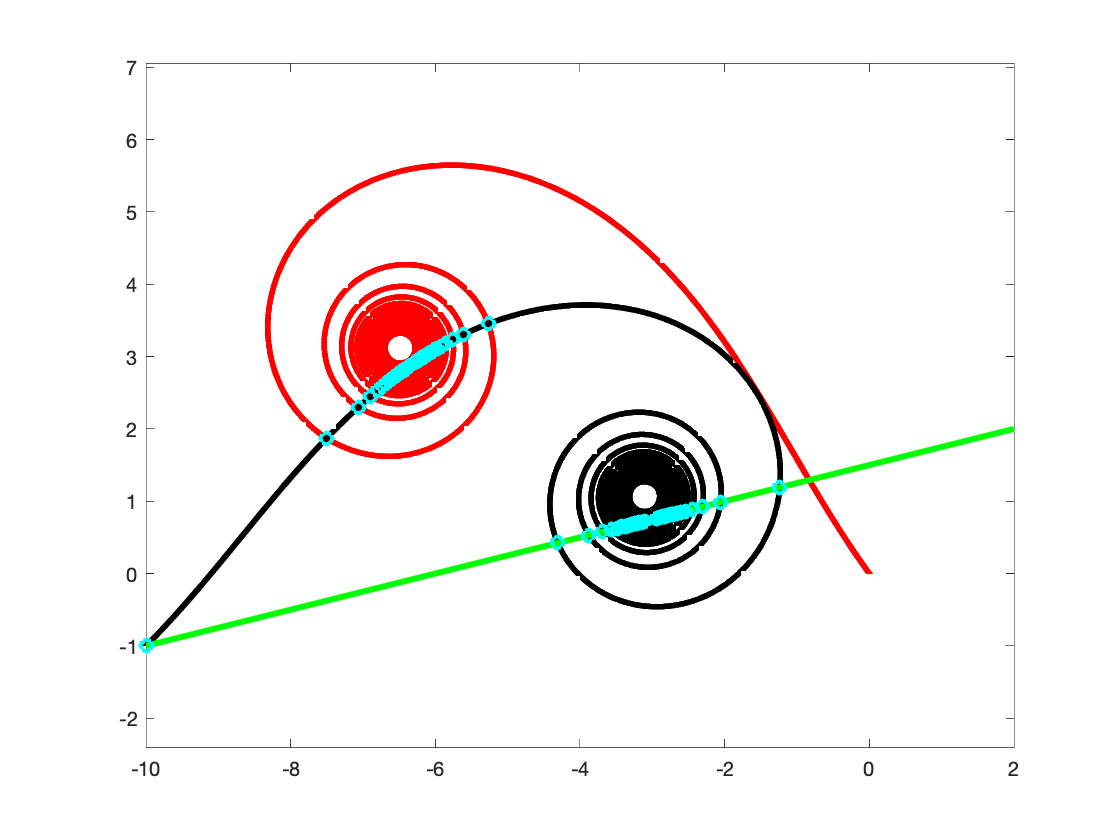


XY1 = C1.eval( s1 );
XY2 = C2.eval( s2 );

plot( XY1(1,:), XY1(2,:), 'ob', 'LineWidth', 2 );
plot( XY2(1,:), XY2(2,:), 'oc', 'LineWidth', 2 );

%XY1 = L.eval( ss1 );
%XY2 = C2.eval( ss2 );
XY1 = C2.eval( sss1 );
XY2 = L.eval( sss2 );

plot( XY1(1,:), XY1(2,:), 'ob', 'LineWidth', 2 );
plot( XY2(1,:), XY2(2,:), 'oc', 'LineWidth', 2 );

axis equal;